# Jared Ham

Mech 513 - Midterm Project

How Fast do Humans Walk on Mars?

### **Project Background**

    It is year 2040, and Mars is being researched for colonization. Locations for bases on Mars are being determined and one criteria that must be considered is disaster planning. As part of disaster planning, the scenario where a mars base has an emergency failure and all members of the base must evacuate to another base must be considered. In this scenario, the Mars astronauts must be able to to transit from one base to the other in less than a day of walking. It is also desireable to have the bases far apart to allow for data to be sampled from a wide varity of locations on Mars. 

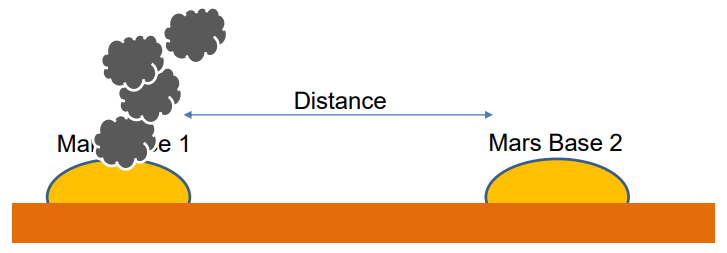

Figure 1: Disaster Scenario

    The acceleration due to gravity on Mars is 3.7 $\frac{m}{s^2 }$ which is about one third of that on earth.  How can we quantify the change in walking speed? Through the Froude Number, a dimensiolness quanity that is used to characterize gait transition and is caluclated using the equation below, v is velocity, g is acceleration due to gravity and L is the length from the ground to the hip joint. 


$$\textrm{Fr}=\frac{v^2 }{g*L}$$


   Based on past research done with the Froude number, a person walks most efficiently at a Froude number of 0.25. And the transition between walking and running occurs at a Froude number of 0.5. In order to determine a confidence interval around the predicitons of walkning velocity on Mars using the Froude number, an experiment on earth will be run. In the experiment the participants will fast walk as fast as they can (this puts them on the edge of walking/running). This will then correspond to a Froude number of 0.5. This data will then be analyzed using Kline McClintock and monte carlo methods, and then extrapolated to a walking speed on Mars. 

### Validation Procedures and Uncertaintity Quantification

In the cell below, the data is entered along with any assumed parameters used throughout the calculations, such as gravity on earth and mars as well as the distance walked during the experiment. 

distanceWalked = 10; %meters
g_earth = 9.80665; %m/s^2
assumedFroudeNumber = 0.5;

classData = [5.65 4.89 4.73 4.96 6.06 4.26 4.99 3.9 5.2 5.4 4.99 4.04 3.79 5.38 4.93 3.79 4.79 4.7 5.17 5.08 5.04 5.5 4.85 5.1; 38.25 37 38 36 32 35 42 40 38 33.5 35 37 41 37 38.5 39 36 41 35.5 36.5 37 33 35.5 38.25]'; % time in seconds, length in inches
classData = [classData(:, 1), classData(:,2) * .0254]; %convert leg length to meters
mydata = [4.38 4.85 4.54 4.95 4.41 ; 42 42 42 42 42  ]'; % time to walk 10 meters, leg length in inches
mydata = [mydata(:,1), mydata(:,2 ) * 0.0254];

Before jumping into the analysis, let's take a step back and present the equations that will be used to analyze the uncertaintity in the model. The following equation will be used to determine the total variance in predicted walking velocity in the model due to pure error, mean error and variance in the leg lengths of the experiment participants.


$$\sigma_v^2 =\sigma_T^2 +\sigma_L^2 {\left(\frac{\partial T}{\partial L}\right)}^2$$



$$\sigma_T^2 =\sigma_{\textrm{pureError}}^2 +\sigma_{\textrm{meanError}}^2$$



$$\sigma_{\textrm{pureError}}^2 ={\textrm{stdev}\left(\left\lbrack \textrm{data}\;\textrm{points}\;\textrm{collected}\;\textrm{on}\;\textrm{myself}\right\rbrack \right)}^2$$


$\sigma_L =$standard deviation of leg length data


$$\frac{\partial T}{\partial \;L}=\frac{\partial }{\partial L}\sqrt{\textrm{Fr}*g*L}=\frac{\sqrt{\;\textrm{Fr}*g}}{2*\sqrt{\;L}}$$
 

Once the total standard deivation ($\sigma_v$) is calculated it will be used to create upper and lower confidence intervals of the model. This analysis will be perfromed at a confidence level of 90% ($\alpha =0\ldotp 9$). It will also assume a normal distribution of the data, allowing use of the student t distribution. 

alpha = 0.9;

In the cell below, the data collected on myself is analyzed to determine the pure error estimate. 

mydata_velocity = 10 ./ mydata(:,1);
mydata_mean_relative_error = mean((mean(mydata_velocity) - mydata_velocity) );
mydata_variance = (std(mydata_velocity) ).^2

mydata_variance = 0.0144

In the cell below, the data collected on other people is analyzed

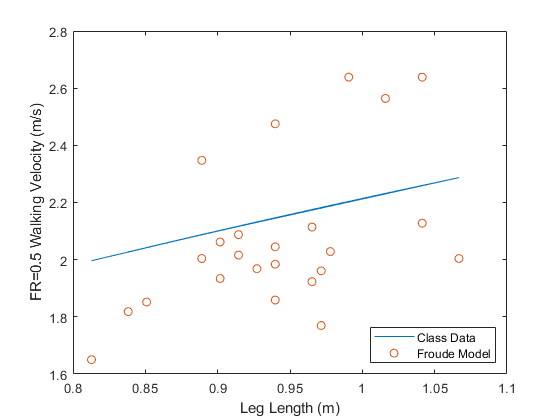

froudeVelocity = sqrt(assumedFroudeNumber * g_earth * classData(:, 2) );
experimentVelocity = distanceWalked ./ classData(:,1);
plot(classData(:,2), froudeVelocity)
hold on
plot(classData(:,2), experimentVelocity, 'o')
xlabel("Leg Length (m)")
ylabel("FR=0.5 Walking Velocity (m/s)")
legend({"Class Data", "Froude Model"}, 'Location', 'southeast')
hold off

Figure 2: Froude Walking Velocity vs. Leg Length

    In Figure 2 above, the froude model is plotted against leg length and all data points collected are shown on the plot for quick comparison of the model to the data. 

relative_speed_CI = tinv((1-alpha)/2, length(classData)-1) * std(experimentVelocity)/sqrt(length(classData))/mean(experimentVelocity);


relative_speed_err = mean((froudeVelocity - experimentVelocity));
validation_variance = max(abs([relative_speed_err + relative_speed_CI relative_speed_err - relative_speed_CI])).^2

validation_variance = 0.0132

Now sum the pure error estimate and the validation variance to get the total tool variance

total_tool_variance = mydata_variance + validation_variance

total_tool_variance = 0.0276

leg_length_variance = std(classData(:,2))^2;

#### Results

relative_speed_err

relative_speed_err = 0.0699

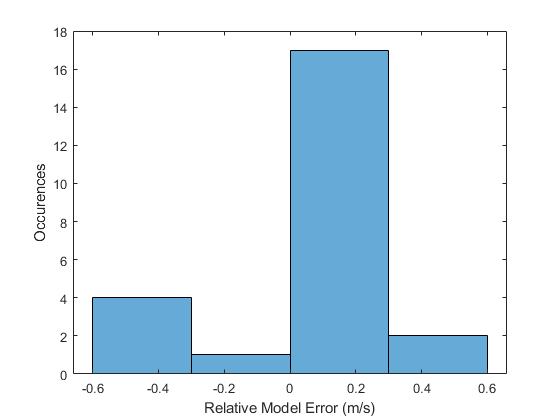

histogram(froudeVelocity - experimentVelocity)
ylabel({'Occurences'});
xlabel({'Relative Model Error (m/s)'});

Figure 3: Histogram of the Relative Model Error (Positive Value is a Model Overprediction)

    Above in Figure 3, a histogram of the Relative Model Error is shown. From the histogram, it can be seen that the model tends to overpredict walking speeds more often than it under predicts. Also, in a majority of the samples, it had a relative error in the range of 0 to 0.30 m/s. The **mean relative error comes in at 0.0699m/s with a variance of 0.0132m/s**

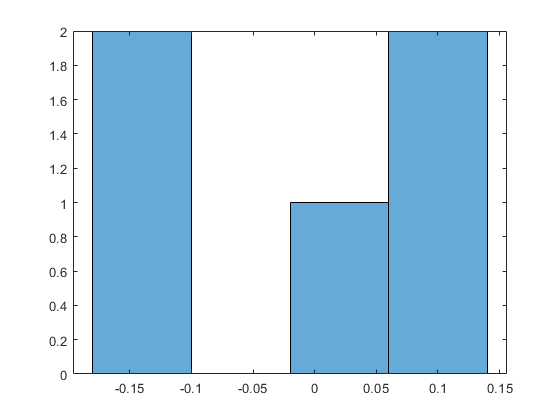

mydata_relative_error = (mydata_velocity - mean(mydata_velocity) ) ;
histogram(mydata_relative_error,4)

Figure 4: Histogram of Pure Error Estimate

    Above in Figure 3, the histogram for Pure Error Estimate is shown. It is pretty evenly distributed on either side of zero and as a result the **mean pure error is 0m/s with a variance of 0.0144m/s**

### Kline McClintock

Now that the validation, total tool variance and variance in the data have been calculated it can all be combined using the Kline McKlintock method. I showed the equation in the section above but will reiterate here for completeness. 


$$\sigma_v^2 =\sigma_T^2 +\sigma_L^2 {\left(\frac{\partial T}{\partial L}\right)}^2$$


dT_dL_squared = sqrt(assumedFroudeNumber * g_earth)./(2*sqrt(classData(:,2))).^2;
total_variance = total_tool_variance + leg_length_variance .* dT_dL_squared;
standard_deviation = sqrt(total_variance);
upperConfidenceInterval = froudeVelocity + standard_deviation;
lowerConfidenceInterval = froudeVelocity - standard_deviation;

Using the results of the Kline-Mclinctock Error Propogation, let us plot the confidence interval bounds of our model. In the figure below, 

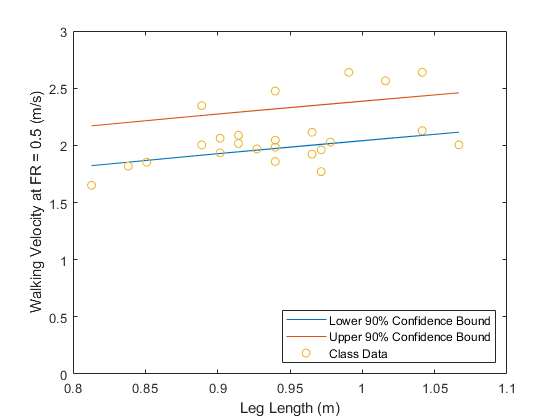

figure
plot(classData(:,2), lowerConfidenceInterval)
hold on
plot(classData(:,2), upperConfidenceInterval)
plot(classData(:,2), experimentVelocity, 'o')
ylim([0,3])
xlabel("Leg Length (m)")
ylabel("Walking Velocity at FR = 0.5 (m/s)")
legend({"Lower 90% Confidence Bound", "Upper 90% Confidence Bound", "Class Data" }, "Location", "southeast")
hold off

Figure 5: Walking Velocity at FR = 0.5 vs Leg Length

Now lets assume that the sample mean closely approximates the population mean for astronaut leg lengths in year 2040 and predict an average walkning velocity on mars. Lets also assume that the mean total standard deviation can be represented by taking the mean of all the standard deviations calculated. This is a fair assumption based on visual inspection of the Figure above, since the upper and lower confidence bounds are fairly linear. Finally, we will also assume that the variances that are calculated at FR=0.5 remain the same for FR=0.25. 

#### Kline McClintock Results

Mean_Leg_Length = mean(legLength);
g_mars = 3.711;%m/s^2
FroudeNumber = 0.25;
Mean_Velocity_on_Mars = sqrt(FroudeNumber * g_mars * Mean_Leg_Length)

Mean_Velocity_on_Mars = 0.9300

Mean_Standard_Deviation = mean(standard_deviation)

Mean_Standard_Deviation = 0.1731

Kline McClintock predicts a walking velocity on mars for the average astronaut to be **0.93m/s **$\pm$** 0.17m/s (2.1mph **$\pm$** 0.38mph)**

### Monte Carlo Simulation

In order to run a monte carlo simulation, a cumulative distribution function (CDF) needs to be created for leg length, relative model error and pure error. This can be done either through assuming a normal distribution for each of these or by using the histogram to create a CDF for each. Matlab has a function built in to emperically create a CDF from a data set, so this is the route that I will take. For each distribution the histogram and the CDF are plotted to allow for a quick sanity check of the CDF against the histogram. 

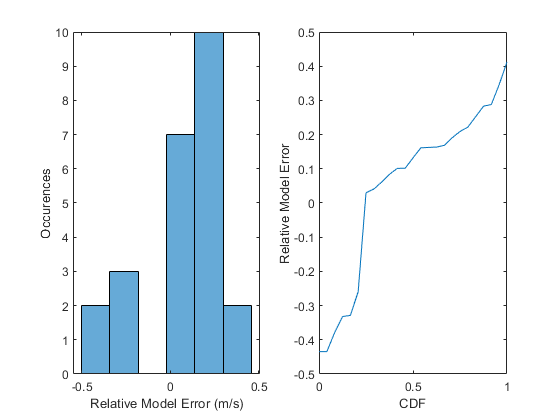

relative_error = froudeVelocity - experimentVelocity;
figure
subplot(1,2,1)
histogram(relative_error, 6)
xlabel("Relative Model Error (m/s)")
ylabel("Occurences")
%relative_error = sort(relative_error)
[relativeError_cdf,relativeError] = ecdf(relative_error); %ecdf is a built in matlab function to emperically create a cdf
subplot(1,2,2)
plot(relativeError_cdf,relativeError )
xlabel("CDF")
ylabel("Relative Model Error")

Figure 6: Relative Model Error Histogram and CDF

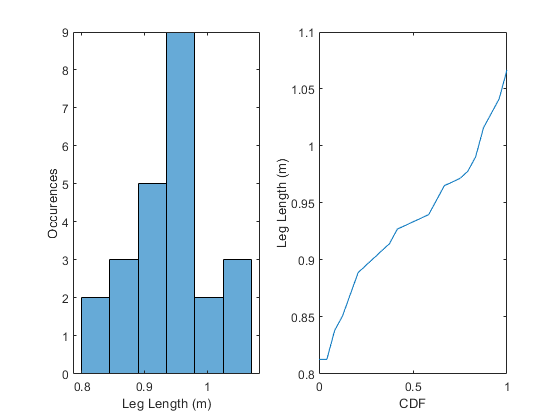

legLength = classData(:,2);
figure
subplot(1,2,1)
histogram(legLength, 6)
xlabel("Leg Length (m)")
ylabel("Occurences")
[legLength_cdf,legLength] = ecdf(legLength);
subplot(1,2,2)
plot(legLength_cdf, legLength)
xlabel("CDF")
ylabel("Leg Length (m)")

Figure 7: Leg Length Histogram and CDF

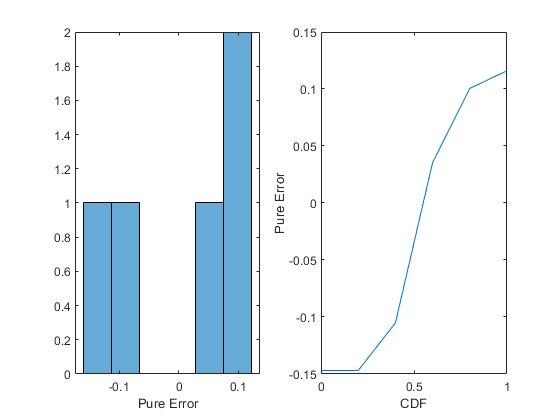

mydata_velocity_relative_error = (mydata_velocity - mean(mydata_velocity)) ;
figure
subplot(1,2,1)
histogram(mydata_velocity_relative_error, 6)
xlabel("Pure Error")
ylabel("")
[experiment_error_cdf, mydata_velocity_relative_error] = ecdf(mydata_velocity_relative_error);
subplot(1,2,2)
plot(experiment_error_cdf, mydata_velocity_relative_error)
xlabel("CDF")
ylabel("Pure Error")

Figure 8: Pure Error Histogram and CDF

Now that a CDF has been created for Relative Error, Experimental Error and Leg Length a Monte Carlo simulation can be run. At each iteration 5 samples will be taken. Then the average and standard dveiation of all iterations and samples will be reported as the predicted walking velocity on Mars. Doing the calculation in this manner, assumes that the sample of data taken will correctly predict the average leg length of the astronauts sent to Mars in year 2040. I believe that the sample size was large enough and diverse enough to make this a fair assumption. 

FroudeNumber = 0.25;
g_mars = 3.711; %m/s^2

num_iterations = 3000;
num_samples = 5;
Predicted_Velocity = zeros(num_iterations, num_samples);
iteration_number = zeros(num_iterations,1);
Mean_Predicted_Velocity = zeros(num_iterations, num_samples);
Std_Predicted_Velocity = zeros(num_iterations, num_samples);
for sample_number = 1:num_samples
    for n=1:num_iterations
        iteration_number(n) = n;
        legLength_n = interp1(legLength_cdf, legLength, rand(1,1));
        relative_error_n = interp1(relativeError_cdf, relativeError, rand(1,1));
        experiment_error_n = interp1(experiment_error_cdf, mydata_velocity_relative_error, rand(1,1));
        Predicted_Velocity(n, sample_number) = sqrt(FroudeNumber *g_mars * legLength_n) + relative_error_n + experiment_error_n ;
        Mean_Predicted_Velocity(n,sample_number) = mean(Predicted_Velocity(1:n,sample_number));
        Std_Predicted_Velocity(n,sample_number) = std(Predicted_Velocity(1:n,sample_number));
    end
end



#### Monte Carlo Results

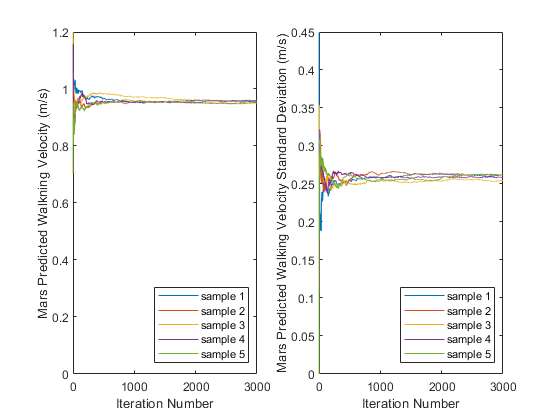

figure
subplot(1,2,1)
plot(iteration_number, Mean_Predicted_Velocity(:,:))
xlabel("Iteration Number")
ylabel("Mars Predicted Walkning Velocity (m/s)")
legend({"sample 1","sample 2","sample 3","sample 4","sample 5"}, "Location", 'southeast')
ylim([0,1.2])
subplot(1,2,2)
plot(iteration_number, Std_Predicted_Velocity)
xlabel("Iteration Number")
ylabel("Mars Predicted Walking Velocity Standard Deviation (m/s)")
legend({"sample 1","sample 2","sample 3","sample 4","sample 5"}, "Location", 'southeast')

Figure 9: Monte Carlo Mean Convergence (left) and Monte Carlo STD Convergence (Right)

    Above in Figure 9 (left), the convergence of the Monte Carlo simulation for each sample is plotted. After about 1500 iterations, it can be seen that all 5 samples have converged to about the 0.95m/s number. In reality, 3,000 samples is likely overkill as you could realisticaly use between 1,000 and 1,500 iterations have have good enough results, but the computation time is not very long so going with an overkill number of iterations is worth it. In Figure 9 (right), the convergence of the standard deviation of the monte carlo simulation is shown. It can be seen that it convergences to around 0.25m/s. 

mean(Predicted_Velocity, "all")

ans = 0.9558

std(Predicted_Velocity, 0,"all")

ans = 0.2597

Monte Carlo predicts an average walking velocity on Mars of **0.95m/s **$\pm$**0.26m/s (2.15mph **$\pm$** 0.58mph)**. 

### Conclusion

Below in Table 1, the results of the Kline McClintock and Monte Carlo simulations for walking speed on Mars are reiterated. It can be seen that each method predicted about the same mean walking velocity however the models differed in the prediction of the standard deviation of the result.

Based on these results I think it is fair to conclude that the minimum average walking speed on Mars will be bounded on the low end by 0.69m/s with 90% confidence. Based on this I think it is safe to move forward with building bases no more than 13.5km apart assuming that there will be 6 hours of available time to transit from one base to another in the event of an emergency. Performing the uncertainity analysis on this model proved usefule, because had the model just been trusted the resulting walking speed would have come in at 0.95m/s which could have resulted in bases being built 20.5km apart, which could have led to a disaster. The analysis gives confidence to the result of the model by bounding it and providing a worst case scenario based on the data that was collected. Without this analysis you would essentially be flying blind in determining how fast an astronaut would walk on Mars and this analysis narrows the result from an essentially infinite domain to one that is much narrower. 

At first my intuition about walking speed on Mars was backwards, I thought that someone would walk faster on Mars thinking that with less gravity less energy would have to be expended. But thinking through the physics at play the fact that someone would walk slower on Mars makes sense, becuase they are not able to develop the same amount of friction while walking that they can on Earth. So this was probably the biggest surprise of this exercise for me. 

Overall, I think the project made good use of the tools that we have developed so far in class. Taking a model that has only been validated on Earth and using it to predict walking velocities on Mars with confidence bounds shows the true power of the tools. However it is hard to understand how valid it is to perform the experiment at FR=0.5 and then extrapolate the results to FR=0.25 and to a different planet. I understand that performing the experiment at FR=0.5 is much easier since it is a run walk boundary, but the model presented above does nothing to account for the difference. It seems that extrapolating on 2 different variables in the model gives the model less validity. But maybe with experience, you begin to know when you can or cannot trust models used to predict outcomes outside of their validation range. I am not sure how it could be done, but I think it would be nice for this model to include experimental data at two different Froude Numbers. I think that it would aid in giving confidence to the ability to extrapolate data from models. As a student I lack real world experience with this sort of analysis so I am unsure of the trust given to extrapolated models in industry. Testing at 2 different Froude Numbers would allow me to predict walking velocities from the FR=0.5 model and then compare to experimental results at FR=0.25. This would allow me to build confidence in the tool and understand when I can and cannot relaibly extrapolate models. Personally I think the most gain students get from school is performing this sort of project and realizing the doubts that they have about the process and realizing how to go about lowering their doubt in the process to be able to confidently apply it in industry. I think this project did a good job of leading me through how to apply the statistical tools we have learned to the real world, but still think there could have been some improvements. 